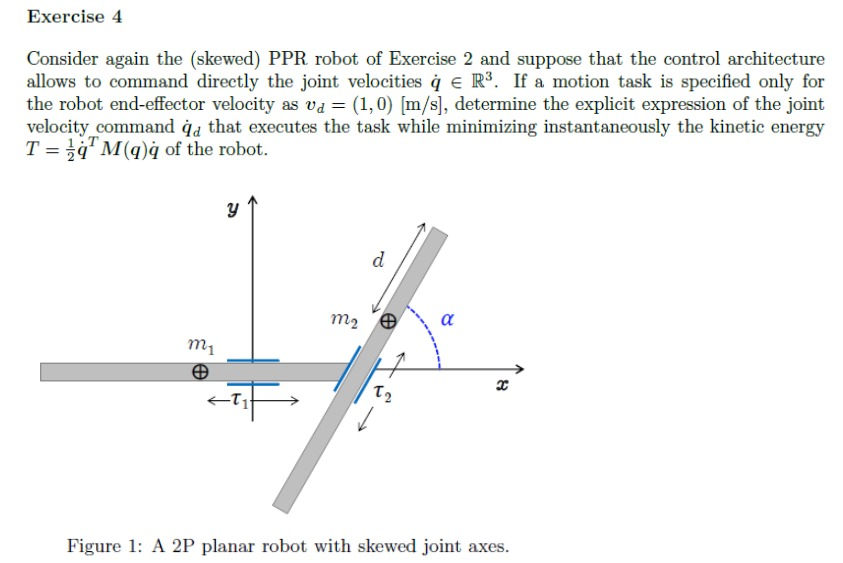

syms m1 m2 alpha tau_1 tau_2 d positive
syms dtau_1 dtau_2 real

% Direct Kinematics and Jacobian
p = [tau_1+(tau_2-d)*cos(alpha);
        (tau_2-d)*sin(alpha);]

$$p = \left(\begin{array}{c} \tau_{1}-\cos\left(\alpha \right)\,\left(d-\tau_{2}\right)\\ -\sin\left(\alpha \right)\,\left(d-\tau_{2}\right) \end{array}\right)$$

J = jacobian(p,[tau_1,tau_2])

$$J = \left(\begin{array}{cc} 1 & \cos\left(\alpha \right)\\ 0 & \sin\left(\alpha \right) \end{array}\right)$$


% Inertia Matrix
T1 = 0.5*m1*dtau_1^2

$$T1 = \frac{{{\mathrm{dtau}}_{1}}^{2}\,m_{1}}{2}$$


x2 = tau_1+(tau_2-d)*cos(alpha);
y2 = (tau_2-d)*sin(alpha);

vx2 = diff(x2,tau_1)*dtau_1 + diff(x2,tau_2)*dtau_2

$$vx2 = {\mathrm{dtau}}_{1}+{\mathrm{dtau}}_{2}\,\cos\left(\alpha \right)$$

vy2 = diff(y2,tau_1)*dtau_1 + diff(y2,tau_2)*dtau_2

$$vy2 = {\mathrm{dtau}}_{2}\,\sin\left(\alpha \right)$$


T2 = simplify(0.5*m2*[vx2 vy2 0]*[vx2; vy2; 0;])

$$T2 = \frac{m_{2}\,\left({{\mathrm{dtau}}_{1}}^{2}+2\,\cos\left(\alpha \right)\,{\mathrm{dtau}}_{1}\,{\mathrm{dtau}}_{2}+{{\mathrm{dtau}}_{2}}^{2}\right)}{2}$$


T=T1+T2;

M11 = diff(diff(T, dtau_1), dtau_1);
M12 = diff(diff(T, dtau_1), dtau_2);
M21 = diff(diff(T, dtau_2), dtau_1);
M22 = diff(diff(T, dtau_2), dtau_2);

M = [M11, M12;
     M21, M22;];

M = simplify(M, 'Steps', 100)

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & m_{2}\,\cos\left(\alpha \right)\\ m_{2}\,\cos\left(\alpha \right) & m_{2} \end{array}\right)$$


% Velocity Command Inertia Weighted-PseudoInverse
v_d = [1;0;];
q_dot = simplify((inv(M)*J.')*(inv(J*inv(M)*J.'))*v_d)

$$q\_dot = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$